clear;
%close all;

%Parameter define
DC_max = 300;
Ld = 15*1e-3;
Lq = 19*1e-3;
Rs = 0.8975*3;
Pasi = 0.1764;
Pole_pair = 3;
Omega_m = 104.7; %% Hz
I_max = 25%17.5;

I_max = 25

Id_max = -10 %-0.35*25;

Id_max = -10

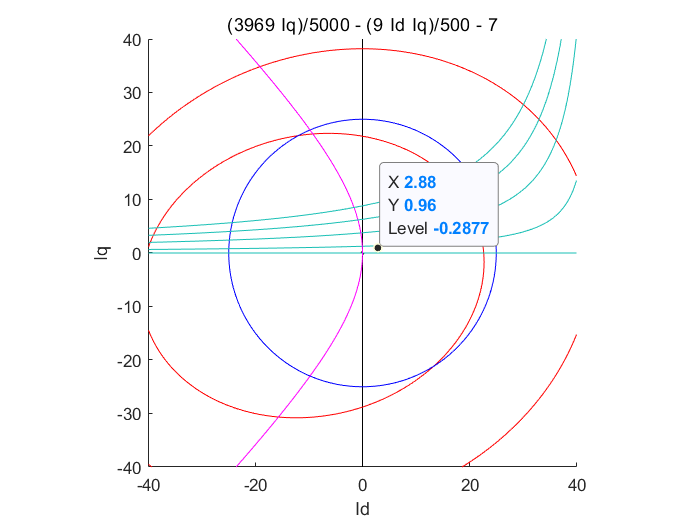

Te = 5;

%Calculate
syms Id Iq;
Omega_e = 314;
% figure set
figure;
axis equal;
%ezplot(Iq*(Id-Id_max),[-30,30,-30,30]);

hold on;
h = ezplot(Id*Iq,[-40,40,-40,40]);
set(h,'color','k');

hold on;
% plot voltage oval
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-40,40,-40,40]);
set(h,'color','r');

Omega_e = Omega_e/2;
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-40,40,-40,40]);
set(h,'color','r');

% plot current circle
hold on ;
h = ezplot(Id.^2+Iq.^2 - I_max.^2,[-40,40,-40,40]);
set(h,'color','b');



% plot T limit
Te = 0;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-40,40,-40,40]);

Te = 1;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-40,40,-40,40]);

Te = 3;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-40,40,-40,40]);

Te = 5;
hold on;
h = ezplot(2*(Lq-Ld)*Id+sqrt(Pasi.^2+(4*(Lq-Ld).^2)*Iq.^2)-Pasi,[-40,40,-40,40]);
set(h,'color','m');
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-40,40,-40,40]);

Te = 7;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-40,40,-40,40]);


xlim([-40 40])
ylim([-40 40])